clear;
dataset = 'ml-latest-small';
fname = 'movie-ratings.zip';
websave(fname,['http://files.grouplens.org/datasets/movielens/',dataset,'.zip']);
unzip(fname);
delete(fname);

moviesTbl = readtable([pwd '/', dataset, '/movies.csv'],'Delimiter',',','TextType','string')

moviesTbl = 9742×3 table
    movieId                   title                                       genres                    
    _______    ____________________________________    _____________________________________________

       1       "Toy Story (1995)"                      "Adventure|Animation|Children|Comedy|Fantasy"
       2       "Jumanji (1995)"                        "Adventure|Children|Fantasy"                 
       3       "Grumpier Old Men (1995)"               "Comedy|Romance"                             
       4       "Waiting to Exhale (1995)"              "Comedy|Drama|Romance"                       
       5       "Father of the Bride Part II (1995)"    "Comedy"                                     
       6       "Heat (1995)"                           "Action|Crime|Thriller"                      
       7       "Sabrina (1995)"                        "Comedy|R

n = length(moviesTbl.title);
year = zeros(n,1);
for i = 1:n
    str = extractBetween(moviesTbl.title(i),'(',')');
    if isempty(str)
        % Missing year
        year(i) = nan;
    else
        % In case of multiple parentheses, use last string extracted
        year(i) = str2double(str(end)); 
    end
end
inds = moviesTbl.movieId(isnan(year));
moviesTbl.year = year

moviesTbl = 9742×4 table
    movieId                   title                                       genres                        year
    _______    ____________________________________    _____________________________________________    ____

       1       "Toy Story (1995)"                      "Adventure|Animation|Children|Comedy|Fantasy"    1995
       2       "Jumanji (1995)"                        "Adventure|Children|Fantasy"                     1995
       3       "Grumpier Old Men (1995)"               "Comedy|Romance"                                 1995
       4       "Waiting to Exhale (1995)"              "Comedy|Drama|Romance"                           1995
       5       "Father of the Bride Part II (1995)"    "Comedy"                                         1995
       6       "Heat (1995)"                           "Action|Crime|Thrill


% Obtain a list of all unique genres in the dictionary
Genres = join(moviesTbl.genres,'|');
Genres = unique(split(Genres,'|'));
Genres(1) = []; % Remove 'no genres' genre
% Create a logical variable for each genre
genres = arrayfun(@(Genres)contains(moviesTbl.genres,Genres),Genres','UniformOutput',false);
% Add the genre variables to the dictionary
moviesTbl = addvars(moviesTbl,genres{:},'NewVariableNames',lower(replace(Genres,'-','')));
% Remove the original genre variable
moviesTbl = removevars(moviesTbl,'genres')

moviesTbl = 9742×22 table
    movieId                   title                    year    action    adventure    animation    children    comedy    crime    documentary    drama    fantasy    filmnoir    horror    imax     musical    mystery    romance    scifi    thriller     war     western
    _______    ____________________________________    ____    ______    _________    _________    ________    ______    _____    ___________    _____


ratingsDS = tabularTextDatastore([pwd '/', dataset, '/ratings.csv'],...
    'SelectedVariableNames',{'userId','movieId','rating'})

ratingsDS =   TabularTextDatastore with properties:

                      Files: {
                             ' ...\machine-learning-ex\ex8\ml-latest-small\ratings.csv'
                             }
                    Folders: {
                             ' ...\downloads\machine-learning-ex\machine-learning-ex\ex8\ml-latest-small'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
      PreserveVariableNames: false
          ReadVariableNames: true
              VariableNames: {'userId', 'movieId', 'rating' ... and 1 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%f', '%f', '%f' ... and 


preview(ratingsDS)

ans = 8×3 table
    userId    movieId    rating
    ______    _______    ______

      1           1        4   
      1           3        4   
      1           6        4   
      1          47        5   
      1          50        5   
      1          70        3   
      1         101        5   
      1         110        4   



ratingsTbl = tall(ratingsDS)

ratingsTbl =

  M×3 tall table

    userId    movieId    rating
    ______    _______    ______

      1           1        4   
      1           3        4   
      1           6        4   
      1          47        5   
      1          50        5   
      1          70        3   
      1         101        5   
      1         110        4   
      :          :         :
      :          :         :




nr = height(ratingsTbl);
nr = gather(nr);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 0.53 sec
Evaluation completed in 0.72 sec


fprintf('There are %d total ratings in the dataset',nr)

There are 100836 total ratings in the dataset


ratingsTbl(ismember(ratingsTbl.movieId,inds),:) = [];

counts = histcounts(ratingsTbl.userId,'BinMethod','Integers');
counts = gather(counts);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 1.1 sec
- Pass 2 of 2: Completed in 0.49 sec
Evaluation completed in 2.1 sec


nu = length(counts);
[counts,usid] = max(counts);
fprintf('There are %d unique user ID''s in the dataset',nu)

There are 610 unique user ID's in the dataset

fprintf('The most prolific reviewer in the dataset has user ID %d and has %d reviews.',usid,counts)

The most prolific reviewer in the dataset has user ID 414 and has 2697 reviews.


ratingsTbl = join(ratingsTbl,moviesTbl)

ratingsTbl =

  M×24 tall table

    userId    movieId    rating                title                year    action    adventure    animation    children    comedy    crime    documentary    drama    fantasy    filmnoir    horror    imax     musical    mystery    romance    scifi    thriller     war     western
    ______    _______    ______    _____________________________    ____


[grp,inds] = findgroups(ratingsTbl.movieId);
inds = gather(inds);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 0.53 sec
Evaluation completed in 0.72 sec


nm = length(inds);
fprintf('There are %d unique movies in the ratings dataset',nm)

There are 9711 unique movies in the ratings dataset

ratingsTbl.movieId = grp

ratingsTbl =

  M×24 tall table

    userId    movieId    rating                title                year    action    adventure    animation    children    comedy    crime    documentary    drama    fantasy    filmnoir    horror    imax     musical    mystery    romance    scifi    thriller     war     western
    ______    _______    ______    _____________________________    ____


numRatings = gather(histcounts(ratingsTbl.movieId,'BinMethod','integers'));

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 1.3 sec
- Pass 2 of 2: Completed in 0.57 sec
Evaluation completed in 2.4 sec


[count,ind] = max(numRatings);
ttl = gather(ratingsTbl.title(find(ratingsTbl.movieId==ind,1)));

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 3: Completed in 0.66 sec
- Pass 2 of 3: Completed in 0.41 sec
- Pass 3 of 3: Completed in 0.45 sec
Evaluation completed in 2.1 sec


fprintf('The most reviewed movie in the dataset is ''%s'' with %d reviews',ttl, count);

The most reviewed movie in the dataset is 'Forrest Gump (1994)' with 329 reviews

histogram(numRatings,'BinWidth',10)
xlabel('# of Reviews')

titles = "Star Wars: Episode " + ["IV","V","VI"] + " "

titles = 1×3 string array
    "Star Wars: Episode IV "    "Star Wars: Episode V "    "Star Wars: Episode VI "


inds = contains(ratingsTbl.title,titles);
rtg =  gather(mean(ratingsTbl.rating(inds)));

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: 0% complete
Evaluation 0% complete



- Pass 1 of 1: Completed in 0.9 sec
Evaluation completed in 1.6 sec


fprintf('The mean rating for the original Star Wars trilogy is: %.2f',rtg);

The mean rating for the original Star Wars trilogy is: 4.20

titles = "Star Wars: Episode " + ["I","II","III"] + " "

titles = 1×3 string array
    "Star Wars: Episode I "    "Star Wars: Episode II "    "Star Wars: Episode III "


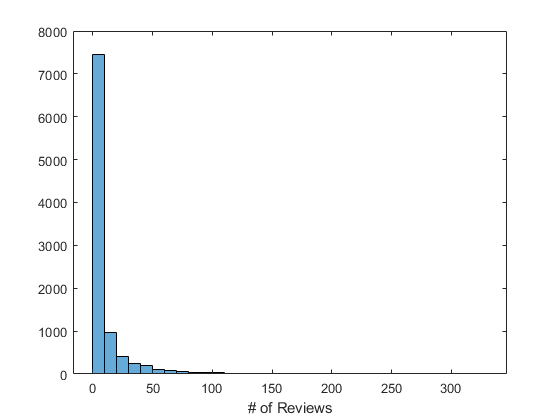

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: 0% complete
Evaluation 0% complete



- Pass 1 of 1: Completed in 0.73 sec
Evaluation completed in 0.98 sec


rtg = gather(mean(ratingsTbl.rating(contains(ratingsTbl.title,titles))));

fprintf('The mean rating for the Star Wars prequels is: %.2f',rtg);

The mean rating for the Star Wars prequels is: 3.20


[means,sums,grp] = grpstats(ratingsTbl.rating,ratingsTbl.year,{'mean','numel','gname'});
[means,sums,grp] = gather(means,sums,grp);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.2 sec
Evaluation completed in 3.1 sec


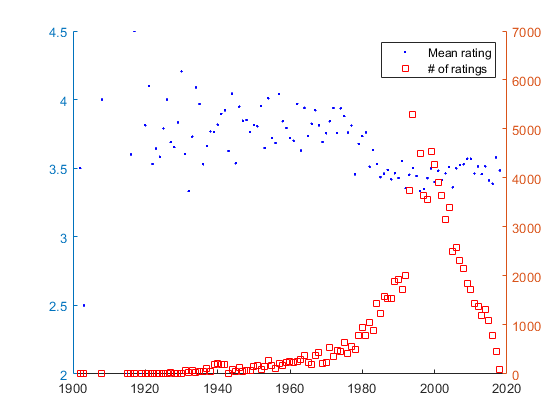

figure; hold on;
yyaxis left;
plot(str2double(grp),means,'b.','MarkerSize',6);
yyaxis right;
plot(str2double(grp),sums,'rsq','MarkerSize',6);
legend({'Mean rating','# of ratings'})

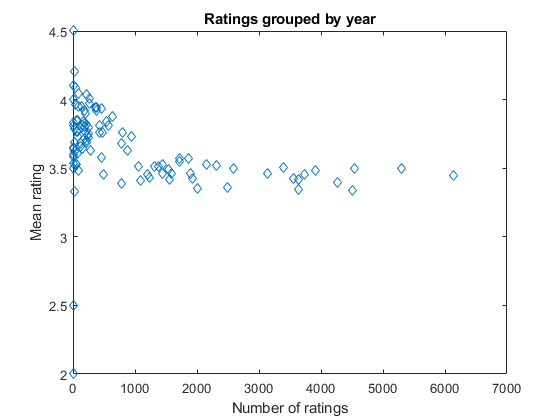


figure;
plot(sums,means,'diamond')
title('Ratings grouped by year')
xlabel('Number of ratings')
ylabel('Mean rating')


globalMean =  3.5;
err = gather(mean(abs(ratingsTbl.rating-globalMean)));

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: 0% complete
Evaluation 0% complete



- Pass 1 of 1: Completed in 0.72 sec
Evaluation completed in 0.98 sec


fprintf('The mean absolute prediction error using the overall mean rating is: %g',err);

The mean absolute prediction error using the overall mean rating is: 0.827


meanRating = gather(splitapply(@mean,ratingsTbl.rating,ratingsTbl.movieId));

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 15 sec
Evaluation completed in 18 sec


ratingsTbl = join(ratingsTbl,array2table([(1:nm)',meanRating,numRatings'],'VariableNames',{'movieId','meanRating','numRatings'}));
meanPred = ratingsTbl.meanRating;
meanPred(ratingsTbl.numRatings<10) = globalMean;
meanPredErr = mean(abs(meanPred-ratingsTbl.rating));
fprintf('The mean absolute error when predicting the mean rating by movie is: %g',gather(meanPredErr))

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 1.5 sec
Evaluation completed in 1.9 sec
The mean absolute error when predicting the mean rating by movie is: 0.736877


tbl = unique(ratingsTbl(:,[2,4,5,end-1,end,6:end-2]),'rows');
tbl = gather(tbl)

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 1.6 sec
Evaluation completed in 2 sec


tbl = 9711×24 table
    movieId                   title                    year    meanRating    numRatings    action    adventure    animation    children    comedy    crime    documentary    drama    fantasy    filmnoir    horror    imax     musical    mystery    romance    scifi    thriller     war     western
    _______    ____________________________________    ____    __________    __________    ______    _________    _________    ______


clearvars -except R ratingsTbl ratingsDS tbl globalMean
[userId,movieId,rating] = gather(ratingsTbl.userId,ratingsTbl.movieId,ratingsTbl.rating);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 0.75 sec
Evaluation completed in 0.91 sec


R = sparse(userId,movieId,rating);

[r,c] = find(R(:,1))

r =      1
     5
     7
    15
    17
    18
    19
    21
    27
    31


c =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1




[nu,nm] = size(R)

nu = 610

nm = 9711



%add your own rating
movieid = 1; % Add the index from the search results
rating = 5; % Select your rating
R(nu+1,movieid) = rating;
% Your ratings:
table(tbl.title(R(end,:)>0),nonzeros(R(end,:)),'VariableNames',{'Movie','Rating'})

ans = 1×2 table
          Movie           Rating
    __________________    ______

    "Toy Story (1995)"      5   



minInCommon = 3;
maxDist = 0.75;
minRtgs = 3;
nbrlist = rangesearch(R,R,maxDist,'Distance',@(x,Y)nndistfun(x,Y,minInCommon));
disp('Your neighbor id''s: ')

Your neighbor id's: 


nbrlist{end}'


ans =

  0×1 empty double column vector




[pred,nnOrMean] = nnpredictfun([userId,movieId],nbrlist,R,tbl,minRtgs);
fprintf('The mean absolute error for the nearest neighbor method is: %g', mean(abs(pred-gather(ratingsTbl.rating))));

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 0.63 sec
Evaluation completed in 0.66 sec
The mean absolute error for the nearest neighbor method is: 0.671283

fprintf('Neighbor ratings were used to make %g percent of predictions.',100*mean(nnOrMean))

Neighbor ratings were used to make 57.5106 percent of predictions.


myNNrating = nnpredictfun([ones(nm,1)*(nu+1),(1:nm)'],nbrlist,R,tbl,minRtgs);
tbl = addvars(tbl,myNNrating,'After','meanRating')

tbl = 9711×25 table
    movieId                   title                    year    meanRating    myNNrating    numRatings    action    adventure    animation    children    comedy    crime    documentary    drama    fantasy    filmnoir    horror    imax     musical    mystery    romance    scifi    thriller     war     western
    _______    ____________________________________    ____    __________    __________    __________    ______    ____


function Dist = nndistfun(x,Y,minInCommon)
maxdist = 4.5; % maximum possible distance
n = size(Y,1);
Dist = zeros(n,1);
inds = x == 0; % movies not rated by user
x(inds) = [];
Y(:,inds) = [];
inCommon = sum(Y>0,2); % num shared movies
inds = inCommon < minInCommon;
Dist(inds) = maxdist;
Y(inds,:) = [];
%X = repmat(x,size(Y,1),1);
%X(Y==0) = 0; % Set movie ratings not rated by both users to 0
dist = sum(abs(x.*(Y>0)-Y),2)./inCommon(~inds); % average absolute difference in shared ratings
Dist(~inds) = dist;
end

function [pred,nnOrMean] = nnpredictfun(Inds,nblist,ratings,movietbl,minRtgs)
n = size(Inds,1); % number of ratings to compute
pred = zeros(n,1); % vector of predicted movie ratings
nnOrMean = logical(pred); % keep track of whether mean or nn used to compute rating
globalMean = mean(nonzeros(ratings));
for k = 1:n
    uid = Inds(k,1); % userId
    mid = Inds(k,2); % movieInd
    neighbors = nblist{uid}; % neighbors
    neighbors(neighbors == uid) = []; % remove 'self' neighbor
    rtgs = ratings(neighbors,mid); % movie ratings by neighbors
    if nnz(rtgs) > minRtgs
        pred(k) = mean(nonzeros(rtgs));
        nnOrMean(k) = 1;
    elseif movietbl.numRatings(mid) > 10
        pred(k) = movietbl.meanRating(mid);
    else
        pred(k) = globalMean;
    end
end
end

